# Import Data

clear all
format shortG

filename = 'log.txt';
% remember: cd 'C:\Users\marti\OneDrive - Danmarks Tekniske Universitet\DTU\2-rotor drone Bachelor'
%filename = 'logFreeFlight10sec.txt';                %shit
%filename = 'logFF20sec10til20sec.txt';              %shit
filename = 'logFreeFlight10secRamteJord17_27.txt';  %shit
%filename = 'logFreeFlight15sec.txt';                %Usable
%filename = 'logYAWprev.txt'
filename='logYAWnewServoFinetune1.txt'

filename = 'logYAWnewServoFinetune1.txt'

%filename = 'logYAWnewServo (1).txt'
%filename = 'log Pitch backwards.txt'
%filename = 'log pitch forward.txt'

cd('C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Flight data')

rawimport = importdata(filename);
rawdata = rawimport.data

rawdata =         10.84            2            0       86.848       -0.345        0.015            0        616.7            0            0        -94.8       0.1016      -2.5197       5.5074       9.3733       -0.005
        30.84            2            0       86.664       -0.345        0.015        0.465        615.3            0            0       -189.2       0.1016      -2.5657        5.651       14.561        0.001
        50.86            2            0       86.664       -0.345            0            0        615.3            0            0       -123.5       0.1016      -2.5884       5.6822       11.123            0
        70.85            2            0       86.664       -0.345            0        0.465        615.3            0            0       -113.8       0.1016      -2.5212       5.7765       10.436        0.002
        90.85            2            0       86.848       -0.345            0            0        616.6            0            0        -97.3       0.10


t = rawdata(:,1)./1000; % 1     Time (s)
arm_state = rawdata(:,2); % 2     Arm state (init, disarmed, armed, fail)
flight_state = rawdata(:,3); % 3     Flight state (on ground, starting, flight, landing)
h_ref = rawdata(:,4); % 4     Height ref (thrust ref)
r_ref = rawdata(:,5); % 5     Roll ref (deg)
p_ref = rawdata(:,6); % 6     Pitch ref (deg)
y_ref = rawdata(:,7); % 7     Yaw ref (deg/s)
h_mixer = rawdata(:,8); % 8     Height value to mixer (thrust ref) o/oo
r_mixer = rawdata(:,9); % 9     Roll value to mixer o/oo
p_mixer = rawdata(:,10); % 10    Pitch value to mixer o/oo
y_mixer = rawdata(:,11); % 11    Yaw value to mixer o/oo
h_pos = rawdata(:,12); % 12    Height position (m) filtered 
r_pos = rawdata(:,13); % 13    Roll angle (deg)
p_pos = rawdata(:,14); % 14    Pitch angle (deg)
y_vel = rawdata(:,15); % 15    Yaw velocity (deg/s)
h_vel = rawdata(:,16); % 16    Height velocity (m/s) does'nt work after
%new ref input

%Sorting all according to time t:
[t, idx] = sort(t);
r_pos = r_pos(idx);
r_ref = r_ref(idx);
p_pos = p_pos(idx);
p_ref = p_ref(idx);
y_vel = y_vel(idx);
y_ref = y_ref(idx);
h_pos = h_pos(idx);
h_vel = h_vel(idx);
h_ref = h_ref(idx);
p_mixer=p_mixer(idx);
r_mixer=r_mixer(idx);
y_mixer=y_mixer(idx);


## Height Position

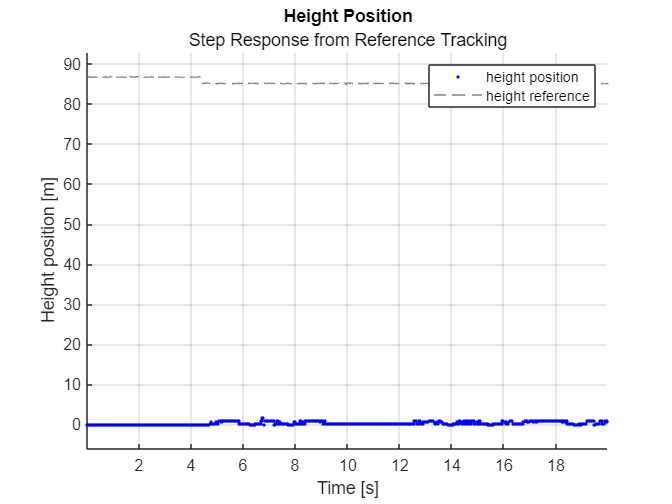

clf
hold on
plot_meas = plot(t,h_pos,'.', 'DisplayName', 'height position');
plot_ref = plot(t,h_ref, '--','DisplayName', 'height reference');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Height Position", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Height position [m]')
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;
hold off

## Height Velocity

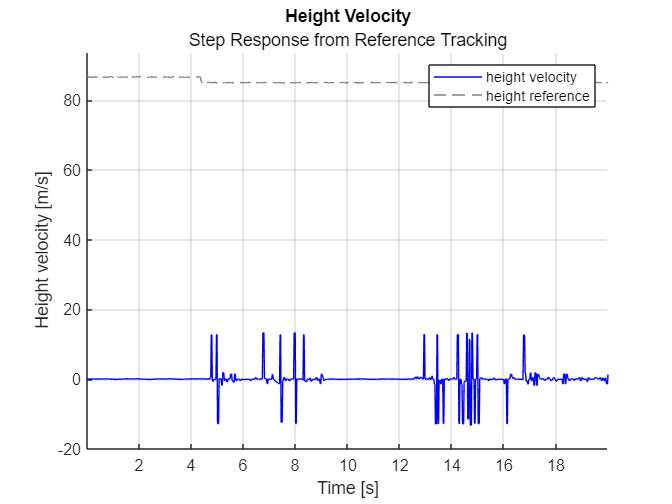

clf
hold on
plot_meas = plot(t,h_vel, 'DisplayName', 'height velocity');
plot_ref = plot(t,h_ref, '--','DisplayName', 'height reference');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Height Velocity", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Height velocity [m/s]')
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;
hold off

## Roll Velocity 

clf
%use this when testing velocity:
v = zeros(length(t)-1,1);
for i = 1:length(t)-1
    v(i) = (r_pos(i+1)-r_pos(i))/(t(i+1)-t(i)) ;
    if (isnan(v(i)))
        if i == 1
            v(i) = 0;
        else
            v(i)=v(i-1);
        end
    end
end
v

v =             0
            0
            0
            0
            0
            0
            0
      -2.3025
      -2.3025
      -2.3025


r_vel_mov = movmean(v,20)

r_vel_mov =      -0.69075
     -0.83727
     -0.95937
      -1.0627
      -1.1512
       -1.228
       -1.222
      -1.2166
      -1.2119
      -1.2077


hold on
%plot_meas = plot(t,r_pos,'.','DisplayName', 'roll position');
plot_meas = plot(t(1:length(r_vel_mov)),r_vel_mov,'DisplayName', 'roll velocity');
plot_ref = plot(t,r_ref, '--','DisplayName', 'roll reference');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Roll Velocity", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Roll position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
length(r_pos)

ans =         4613


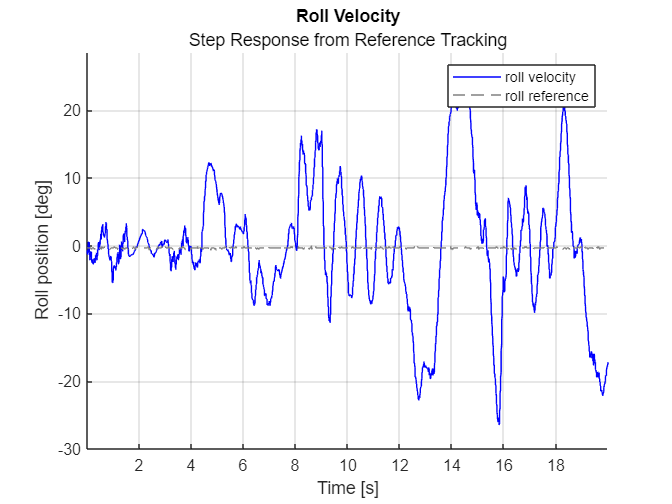

xlim tight
ylim padded
lgd = legend;
hold off

## Roll Position (angle)

clf
hold on
plot_meas = plot(t,r_pos,'DisplayName', 'roll position');
plot_ref = plot(t,r_ref, '--','DisplayName', 'roll reference');
%plot_mixer = plot(t,r_mixer./4, '--','DisplayName', 'roll mixer');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Roll Position", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Roll position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
length(r_pos)

ans =         4613


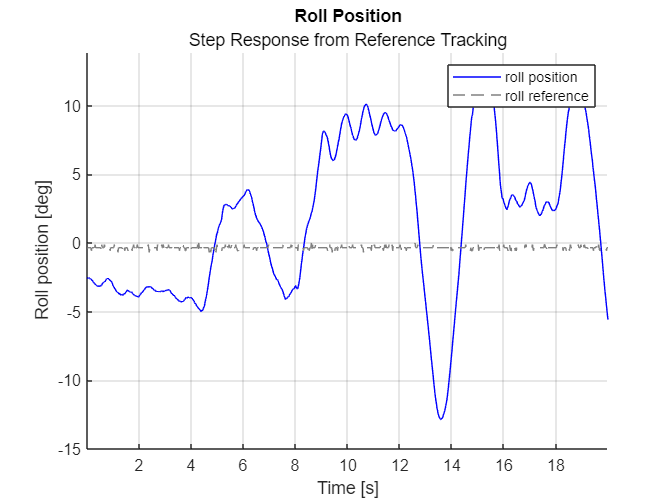

xlim tight
ylim padded
lgd = legend;
hold off

## Pitch Velocity

%use this when testing velocity:
v = zeros(length(t)-1,1);
for i = 1:length(t)-1
    v(i) = (p_pos(i+1)-p_pos(i))/(t(i+1)-t(i)) ;
    if (isnan(v(i)))
        if i == 1
            v(i) = 0;
        else
            v(i)=v(i-1);
        end
    end
end
v

v =             0
            0
            0
            0
            0
            0
            0
        7.179
        7.179
        7.179


p_vel_mov = movmean(v,20)

p_vel_mov =        2.1537
       2.6105
       2.9913
       3.3134
       3.5895
       3.8288
       3.6869
       3.5617
       3.4504
       3.3508



clf
hold on
plot_meas = plot(t(1:length(p_vel_mov)),p_vel_mov, 'DisplayName', 'pitch Velocity');
plot_ref = plot(t,p_ref, '--','DisplayName', 'pitch reference');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Pitch Velocity", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;
idx

idx =            1
         587
        1161
        1738
        2326
        2919
        3503
        4092
           2
         588


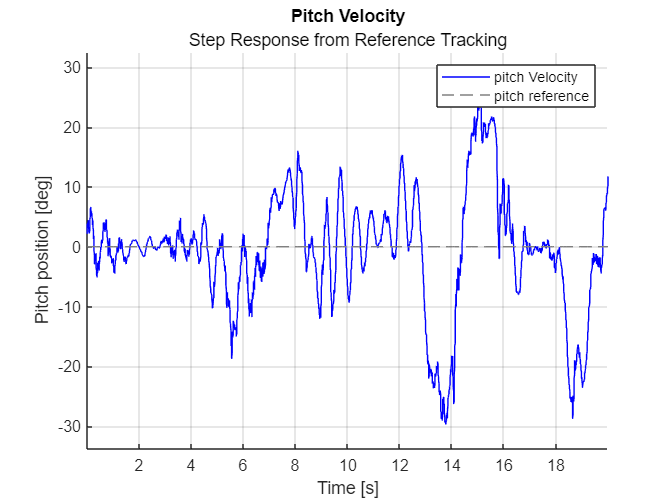

hold off

## Pitch Position



clf
hold on
plot_meas = plot(t,movmean(p_pos+p_mixer*0.0505,20), 'DisplayName', 'pitch position');
plot_ref = plot(t,p_ref, '--','DisplayName', 'pitch reference');
plot_mixer = plot(t,movmean(p_mixer,1),'DisplayName', 'pitch mixer');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Pitch Position", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;
idx

idx =            1
         587
        1161
        1738
        2326
        2919
        3503
        4092
           2
         588


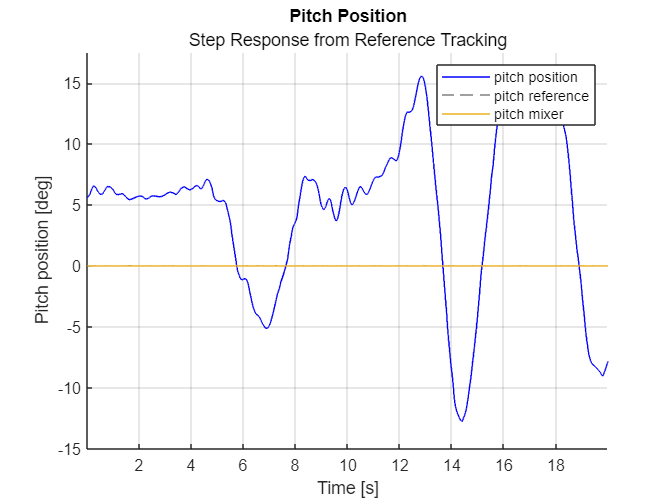

hold off

## Yaw Velocity

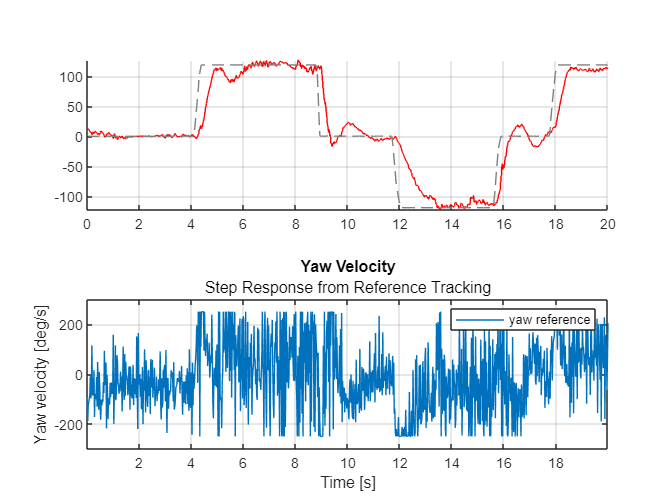


clf
subplot(2,1,1)
%plot_meas = plot(t,y_vel, 'DisplayName', 'yaw velocity','Color','Black');

hold on
plot_meas_filt = plot(t,movmean(y_vel,20), 'DisplayName', 'yaw velocity Filtered','Color','Red');
plot_ref = plot(t,y_ref, '--','DisplayName', 'yaw reference');
hold off
grid on
subplot(2,1,2)
plot_mixer = plot(t,y_mixer, 'DisplayName', 'yaw reference');
plot_ref.Color = [0.5, 0.5, 0.5];
title("Yaw Velocity", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;

length(y_vel)

ans =         4613


%plot(y_vel(t>2 & t<4))
variance=var(y_vel(t>2 & t<4))

variance =        13.432


standardDeviancen=std(y_vel(t>2 & t<4))

standardDeviancen =         3.665


## System response information

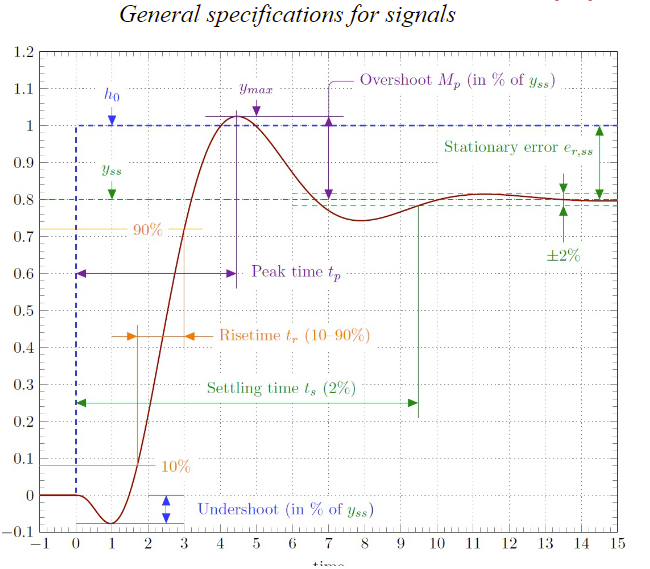

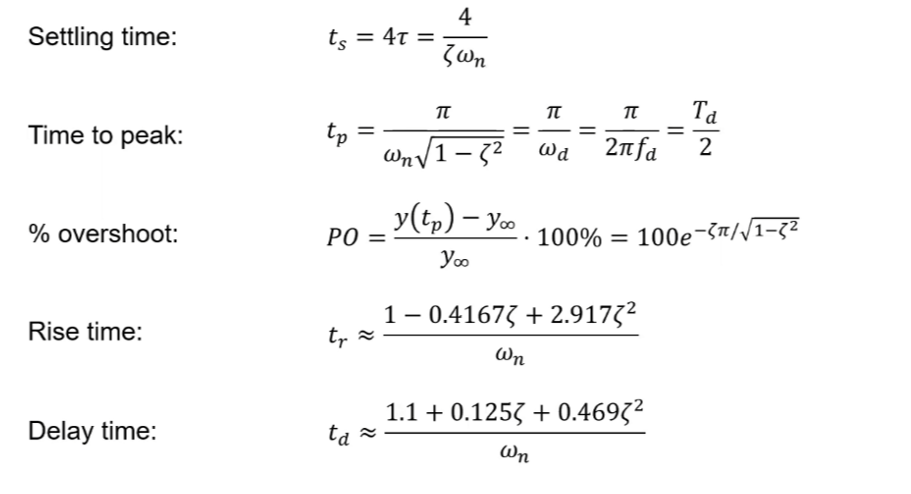

%{
% Settling time 1%:
t_step = 12.550 %sec
y_ref_step = 120
i = length(y_vel);
settlingtime = t(end);
while(abs(y_vel(i)+y_ref_step)<=0.08*y_ref_step+y_ref_step)
    settlingtime = t(i)-t_step;
    i = i-1;
end
disp("Settling time: " + settlingtime + "s")
%}
%{
%Percent overshoot
[d, i_O] = min(abs(t-7))
PO = (max(y_vel) - y_ref(i_O))/y_ref(i_O)

% System properties
[d, i_O] = min(abs(t-7))
y_vel_mov=movmean(y_vel,20)
sys_step = stepinfo(y_vel_mov(1:i_O), t(1:i_O), y_ref(i_O))


syms zeta
eq1 = 100*exp(-zeta*pi/sqrt(1-zeta^2)) == sys_step.Overshoot
zeta = eval(rhs(isolate(eq1, zeta)))

syms w_n
eq2 = (1-0.4167*zeta + 2.917*zeta^2)/w_n == sys_step.RiseTime
w_n = eval(rhs(isolate(eq2, w_n)))

% Approximate to a second order system:
s = tf('s')
sys = w_n^2 / (s^2 + 2*zeta*w_n*s + w_n^2)
[y,tout] = step(sys)

clf
hold on 
plot(3.7+tout, y*120)
plot(7.3+tout, 120+y*(-120))
plot(10+tout, y*(-120))
plot(12.5+tout, -120+y*120)
plot(t, y_vel)
hold off
%}
